# VCO Characteristic Curve Measurement

This script simulates the recording of VCO output frequency (f_VCO)

based on control voltage (V), according to the lab instructions.

## Define control voltage values

V = 1.0:0.4:7.0; % Voltage steps from 1.0V to 7.0V in 0.4V steps

## Preallocate arrays for measured frequency (fr) and VCO frequency (f_VCO)

fr = zeros(size(V));     % Frequency measured at User 1 port
fVCO = zeros(size(V));   % VCO output frequency (calculated)

## Instruction

Connect "User 1" port to oscilloscope.

Use T1_Control_Voltage.exe to vary voltage from 1.0V to 7.0V in 0.4V steps.

Measure frequency fr at each voltage step.

## Measured Frequency Values (in kHz):

fr = [358.7, 361.62, 364.04, 366.17, 368.19, 370.16, 371.88, 373.55, 375.09, 376.65, 378.12, 379.58, 380.86, 382.14, 383.3, 384.9];

## Calculate VCO frequency

According to the instruction: f_r = f_VCO / 65536 -> f_VCO = f_r * 65536

fVCO = (fr * 1e3 * 65536)/1e9; %result in GHz

## Display Results in Table

T = table(V', fr', fVCO', 'VariableNames', {'V', 'f_r_kHz', 'f_VCO_GHz'});
disp('Table 4.1: Measured results of the VCO''s characteristic');

Table 4.1: Measured results of the VCO's characteristic


disp(T);

     V     f_r_kHz    f_VCO_GHz
    ___    _______    _________

      1     358.7      23.508  
    1.4    361.62      23.699  
    1.8    364.04      23.858  
    2.2    366.17      23.997  
    2.6    368.19       24.13  
      3    370.16      24.259  
    3.4    371.88      24.372  
    3.8    373.55      24.481  
    4.2    375.09      24.582  
    4.6    376.65      24.684  
      5    378.12       24.78  
    5.4    379.58      24.876  
    5.8    380.86       24.96  
    6.2    382.14      25.044  
    6.6     383.3       25.12  
      7     384.9      25.225  



## Calculate Interpolated VCO frequency

stepsize = 0.01;
V_fine = 1.0:stepsize:7.0;
f_VCO_interpol = interp1(V, fVCO, V_fine, 'spline');



## Calculate Ideal Interpolation

Offset_min = 0.07;
Offset_max = 0.01;
Vmin = min(f_VCO_interpol)+ Offset_min;
Vmax = max(f_VCO_interpol)+ Offset_max;
dist = Vmax-Vmin;
dim = size(V_fine);
steps = dist / dim(2);
f_VCO_ideal = Vmin:steps:Vmax;
stepsize2 = 6 / 601;
V_fine_2 = 1:stepsize2:7;

## Plot VCO Characteristic Curve

% figure;
% plot(V, fVCO, '-o', 'LineWidth', 2);
% xlabel('Control Voltage V (V)');
% ylabel('VCO Output Frequency f_{VCO} (GHz)');
% title('VCO Characteristic Curve');
% grid on;


## Plot interpolated VCO Characteristic Curve

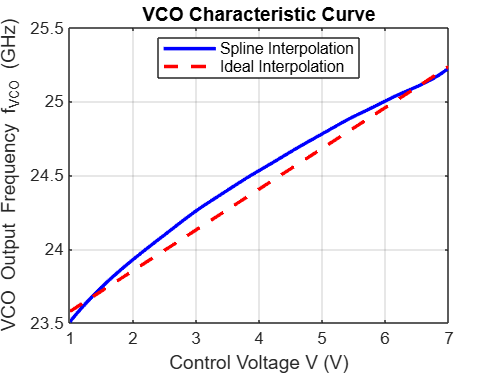

figure;
plot(V_fine, f_VCO_interpol, 'b-', 'LineWidth', 2);      
hold on;
plot(V_fine_2, f_VCO_ideal, 'r--', 'LineWidth', 2);
hold off;
xlabel('Control Voltage V (V)');
ylabel('VCO Output Frequency f_{VCO} (GHz)');
title('VCO Characteristic Curve');
legend('Spline Interpolation', 'Ideal Interpolation','Location', 'best');
grid on;

## Specify the control voltage V_C for a triangular FMCW RADAR using measured VCO Curve

Given:

f_0 = 24 GHz

B = 500 MHz

f_DA = 100 kHz  -> 500MHz / 100 kHz = 5000

T_sweep = 10 ms

## Get relevant voltage range

% Frequecy range in GHz
f_min = 23.75;
f_max = 24.25;
T_sweep = 10; %ms

% mask frequencies of the relevant region
%mask = f_VCO_ideal((f_VCO_ideal >= f_min) & (f_VCO_ideal <= f_max))
%mask = (f_VCO_ideal >= f_min) & (f_VCO_ideal <= f_max)

% Choose the related voltages to the frequencies
%V_selected = V_fine_2(mask)



df = 0.0001;         % 100 kHz = 0.0001 GHz

% Step 2: Create desired frequency array with 100kHz steps
f_uniform = f_min:df:f_max;

% Step 3: Invert the interpolation: find V values for desired f values
% Use interp1 with frequency as x and voltage as y
%V_interp = interp1(f_VCO_ideal, V_fine_2, f_uniform, 'spline');
V_interp = interp1(f_VCO_interpol, V_fine, f_uniform, 'spline');

% Optional: remove any NaNs due to extrapolation
valid_idx = ~isnan(V_interp)

valid_idx = 1x5001 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


V_interp = V_interp(valid_idx)

V_interp =     1.5212    1.5215    1.5217    1.5220    1.5222    1.5224    1.5227    1.5229    1.5232    1.5234    1.5237    1.5239    1.5242    1.5244    1.5247    1.5249    1.5251    1.5254    1.5256    1.5259    1.5261    1.5264    1.5266    1.5269    1.5271    1.5274    1.5276    1.5278    1.5281    1.5283    1.5286    1.5288    1.5291    1.5293    1.5296    1.5298    1.5301    1.5303    1.5305    1.5308    1.5310    1.5313    1.5315    1.5318    1.5320    1.5323    1.5325    1.5328    1.5330    1.5333


V_full_sweep = [V_interp flip(V_interp(1:end-1))]

V_full_sweep =     1.5212    1.5215    1.5217    1.5220    1.5222    1.5224    1.5227    1.5229    1.5232    1.5234    1.5237    1.5239    1.5242    1.5244    1.5247    1.5249    1.5251    1.5254    1.5256    1.5259    1.5261    1.5264    1.5266    1.5269    1.5271    1.5274    1.5276    1.5278    1.5281    1.5283    1.5286    1.5288    1.5291    1.5293    1.5296    1.5298    1.5301    1.5303    1.5305    1.5308    1.5310    1.5313    1.5315    1.5318    1.5320    1.5323    1.5325    1.5328    1.5330    1.5333


f_uniform = f_uniform(valid_idx)

f_uniform =    23.7500   23.7501   23.7502   23.7503   23.7504   23.7505   23.7506   23.7507   23.7508   23.7509   23.7510   23.7511   23.7512   23.7513   23.7514   23.7515   23.7516   23.7517   23.7518   23.7519   23.7520   23.7521   23.7522   23.7523   23.7524   23.7525   23.7526   23.7527   23.7528   23.7529   23.7530   23.7531   23.7532   23.7533   23.7534   23.7535   23.7536   23.7537   23.7538   23.7539   23.7540   23.7541   23.7542   23.7543   23.7544   23.7545   23.7546   23.7547   23.7548   23.7549


timestep = T_sweep / 5000

timestep = 0.0020

time = 0:timestep:2*T_sweep

time =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


% Upward sweep

% Downward sweep


## Plot the V_c(t) curve        

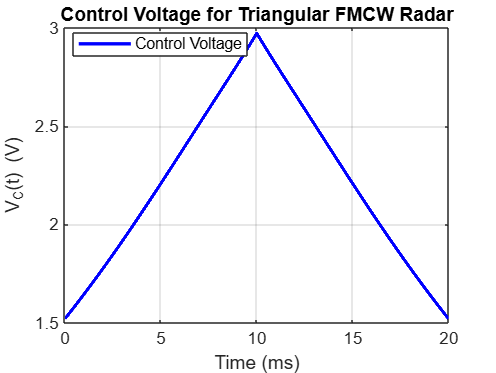

figure;
plot(time, V_full_sweep, 'b-', 'LineWidth', 2);      
xlabel('Time (ms)');
ylabel('V_C(t) (V)');
title('Control Voltage for Triangular FMCW Radar');
legend('Control Voltage', 'Location', 'best');
grid on;

## Why is the VCO’s characteristic curve needed before the radar measurement?

Because the VCO output frequency is not perfectly linear to it's input voltage. Therefore we have to measure it's characteristic curve and map the input voltage values to the actually generated frequencies to ensure, that the frequency sweep we generate behaves the way we want.